filename = "room.pcd";
pointCloud = pcread(filename);
pcshow(pointCloud);

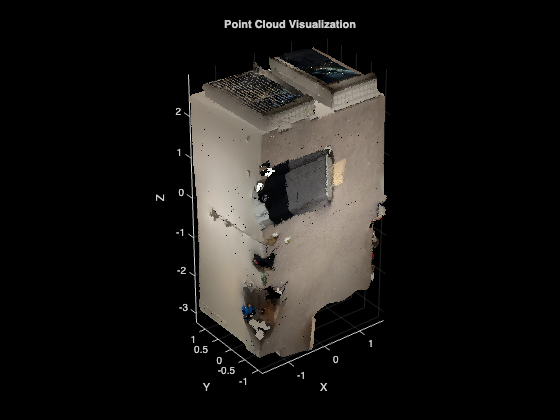

xlabel('X');
ylabel('Y');
zlabel('Z');
title('Point Cloud Visualization');

function rir = generateRIRFromLiDAR(pointCloud, sourcePosition, microphonePosition, soundSpeed, sampleRate, maxDistance)
    % pointCloud: Nx3 matrix of LiDAR points (x, y, z)
    % sourcePosition: 1x3 vector of source position (x, y, z)
    % microphonePosition: 1x3 vector of microphone position (x, y, z)
    % soundSpeed: Speed of sound in meters per second
    % sampleRate: Sample rate in Hz
    % maxDistance: Maximum distance for reflections (adjust as needed)

    % Calculate distances
    sourceToMicDistance = norm(microphonePosition - sourcePosition);
    distances = sqrt(sum((pointCloud - microphonePosition).^2, 2));

    % Filter points within maxDistance
    validPoints = distances <= maxDistance;
    validPointCloud = pointCloud(validPoints, :);

    % Calculate distances from valid points to source and mic
    distancesToSource = sqrt(sum((validPointCloud - sourcePosition).^2, 2));
    distancesToMic = sqrt(sum((validPointCloud - microphonePosition).^2, 2));

    % Calculate time delays
    timeDelaysToSource = distancesToSource / soundSpeed;
    timeDelaysToMic = distancesToMic / soundSpeed;

    % Calculate RIR
    t = 0:1/sampleRate:max([max(timeDelaysToSource), max(timeDelaysToMic)]);
    rirToSource = zeros(size(t));
    rirToMic = zeros(size(t));

    for i = 1:length(validPointCloud)
        indexToSource = round(timeDelaysToSource(i) * sampleRate) + 1;
        indexToMic = round(timeDelaysToMic(i) * sampleRate) + 1;

        if indexToSource <= length(rirToSource)
            rirToSource(indexToSource) = rirToSource(indexToSource) + 1;
        end

        if indexToMic <= length(rirToMic)
            rirToMic(indexToMic) = rirToMic(indexToMic) + 1;
        end
    end

    % Normalize RIRs
    rirToSource = rirToSource / max(rirToSource);
    rirToMic = rirToMic / max(rirToMic);

    % Combine RIRs (optional)
    rir = rirToSource + rirToMic;

    % Normalize combined RIR
    rir = rir / max(rir);
end

